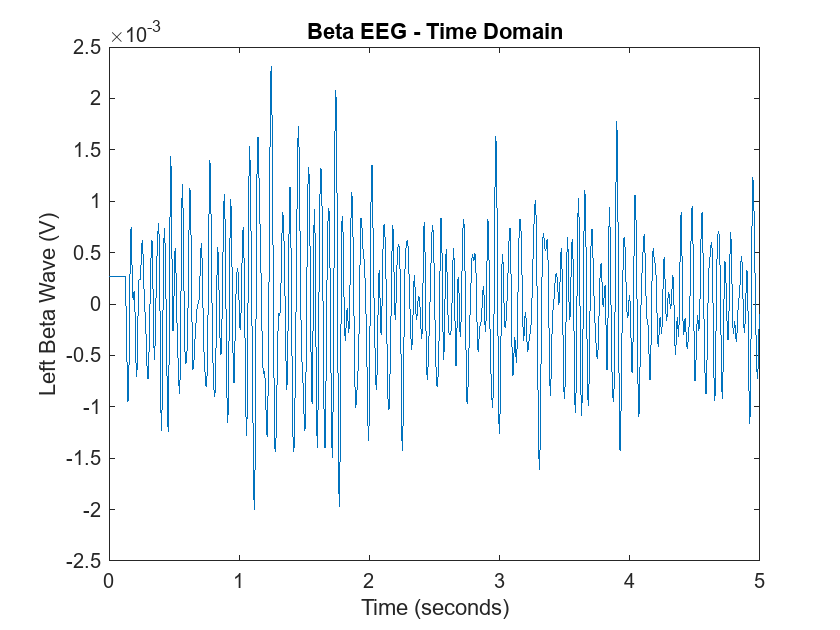

EN_time = 2.1013e-06

EN_frequency = 2.1015e-06

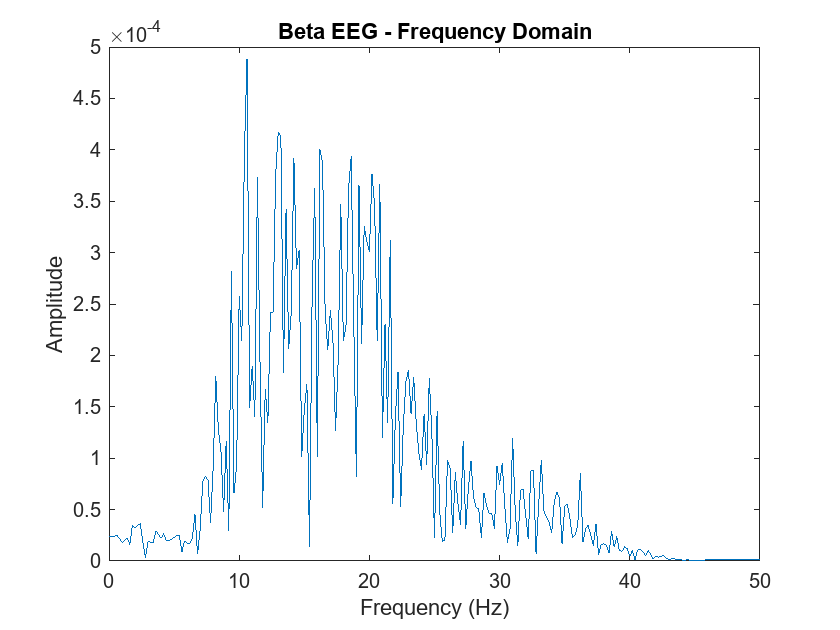

% Fourier transform of alpha and beta EEG signal

% Saun-Jay Samuels, Florida Gulf Coast University 2026

clc;

% Extract Data
EEG_DATA = MDSSAFBOTHExportS3;
Alpha = EEG_DATA.LeftAlphaWaves;
Beta  = EEG_DATA.LeftBetaWaves;

% Set up variables
fs = 200;
dt = 1/fs;
N = length(Alpha);
t = (0:N-1)*dt;
x = Alpha';

% Plot left alpha waves
figure(1);
plot(t,x)
ylabel('Left Alpha Wave (V)');
xlabel('Time (seconds)');
title('Alpha EEG - Time Domain');

k = N;
X = fft(x)*dt;
X = abs(X);
y = fft(x);
y = abs(y);
y = y/fs;
f = (0:length(y)-1)*fs/length(y);
df = fs/N;
f = (0:N-1)*df;

figure(2);
plot(f, y)
ylabel('Amplitude');
xlabel('Frequency (Hz)');
title('Alpha EEG - Frequency Domain');
EN_time = trapz(t,(x.^2));
EN_frequency = sum(y.^2) * df;

xlim([0,50]);